clc
clear all
close all
options = simset('SrcWorkspace','current'); % Execute le circuit

% miroir = sim('simulink_miroir_de_courant',[],options);
% save miroir_variable miroir
% npn = sim('simulink_npn',[],options);
% save npn_variable npn
% pnp = sim('simulink_pnp',[],options);
% save pnp_variable pnp

load miroir_variable.mat miroir

## TP1

**Théorie**

**Pratique**

## TP2

**Théorie**

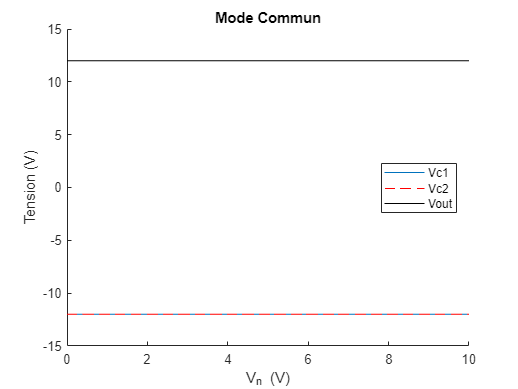

figure
hold on
% plot(out.Vc1.time,out.Vc1.signals.values,'k')
% plot(out.Vc2.time,out.Vc2.signals.values,'--r')
plot(miroir.Miroir_Vc1.time,miroir.Miroir_Vc1.signals.values)
plot(miroir.Miroir_Vc2.time,miroir.Miroir_Vc2.signals.values,'--r')
plot(miroir.Miroir_Vout.time,miroir.Miroir_Vout.signals.values,'k')
legend('Vc1','Vc2','Vout','location','best')
title('Mode Commun')
xlabel("V_i_n (V)")
ylabel("Tension (V)")
hold off

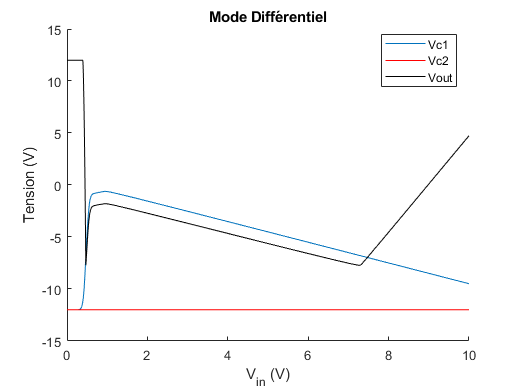


figure
hold on
plot(miroir.Diff_Vc1.time,miroir.Diff_Vc1.signals.values)
plot(miroir.Diff_Vc2.time,miroir.Diff_Vc2.signals.values,'r')
plot(miroir.Diff_Vout.time,miroir.Diff_Vout.signals.values,'k')
legend('Vc1','Vc2','Vout','location','best')
title('Mode Différentiel')
xlabel("V_i_n (V)")
ylabel("Tension (V)")
hold off

**Pratique**

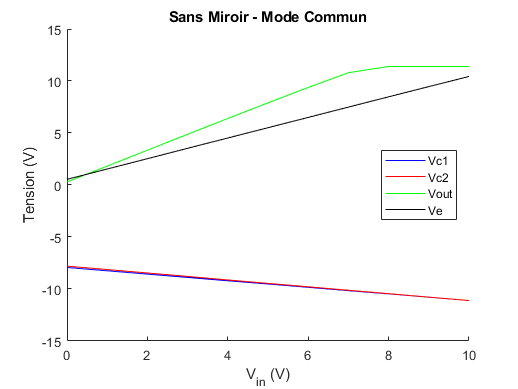

Vin=0:1:10;
%------ Montage sans miroir de courant
% Mode Commun
Vc1=[-7.93 -8.25 -8.57 -8.89 -9.21 -9.52 -9.84 -10.16 -10.47 -10.79 -11.11];
Vc2=[-7.80 -8.13 -8.46 -8.79 -9.13 -9.46 -9.79 -10.12 -10.45 -10.78 -11.11];
Vout=[296e-3 1.821 3.35 4.88 6.40 7.90 9.38 10.80 11.40 11.40 11.40 ];
Ve=[544e-3 1.538 2.53 3.53 4.52 5.51 6.50 7.49 8.48 9.46 10.44];

figure
hold on
plot(Vin,Vc1,'b')
plot(Vin,Vc2,'r')
plot(Vin,Vout,'g')
plot(Vin,Ve,'k')
legend('Vc1','Vc2','Vout','Ve','location','best')
title('Sans Miroir - Mode Commun')
xlabel("V_i_n (V)")
ylabel("Tension (V)")


% Mode Différentiel


%------ Montage avec miroir de courant
% Mode Commun


% Mode Différentiel